# BEAM PROPAGATION SCRIPT

This MATLAB sctipt works to propagate any wavelike beam in space. Fourier Optics are used to model this propagation.

% Begin Script
clear; close all; clc;

% Define General Parameters
n=9;        %
N=2.^n;     %Definition of problem
lx=5;       %Spatial limits
Zm=0.3;     %Spatial limit of propagation
dz=0.01;    %Delta of propagation
nz=Zm./dz;  %

x=linspace(-lx,lx,N+1); x=x(1:N);   %Create an axis of cartesian space
[x,y]=meshgrid(x);                  %Meshrid cartesian space 
[phi,r]=cart2pol(x,y);              %Define Polar Coordinates
Kx=(-N/2:(N/2)-1).*pi./lx;          % K vector
[Kx,Ky]=meshgrid(Kx);               % Kx and Ky
z=(0:dz:Zm);                        % Propagation axis

uz=zeros(size(z));  %Prallocate
ux=zeros(N,length(z));  %Preallocate


Create a Switch to limit the aperture of the pupil.

pupil = "square";

switch pupil
    case "square"
        M=0.*x*y;
        A=find(abs(x)<=0.3 & abs(y)<=0.3);
        M(A)=1;
end
clear pupil

Fase de la lente normalizada ??

- Depende de la curvatura

f=0.10; %Distancia focal
% fszm=f/(1+f.^2);
tn=exp(-i*(r.^2)./f);%
%tn=1;

Calculate the first fourier transform to generate "PROPAGATOR" ??

- Parte de z

prp=fftshift(exp((-1i*dz.*(Kx.^2+Ky.^2)/4.0))); clear Kx Ky
%REACOMODO 

Aberrations

%--------Coma--------

%Ze=Bd.*(r./R).^3.*cos(phi);

%--------Astigmatismo--------
%Ze=Bd.*(r./R).^2.*(cos(phi).^2);
%Ze=Bd.*(r./R).^2.*(cos(2.*phi));

Field eqns

%--------Curvatura de Campo--------
%Ze=Bd.*(r./R).^2;

%--------Esferica--------
%Ze=Bd.*((r./R).^4);

%--------Distorci?n--------
%Ze=Bd.*(r./R).*cos(phi);

%--------Campo--------
x=linspace(-lx,lx,N+1); x=x(1:N);
%Aberracion
%u=M.*tn.*exp(1i.*Ze);


Define Beam of light

beam = "Bessel";

switch beam 
    case "Bessel"
        u=besselj(0,5*r).*(r<(0.9.*lx));
        %u=M.*besselj(0,5*r).*(r<(0.9.*lx));
    case "Gausian"
        u = 2.* exp(-(r/0.6).^2); 
    case "Spherical"
        u = 1./r .* exp(r);
    case "Planewaves"
        u =0.3 * ones(512,512); 
end

uz(1)=u(N/2+1,N/2+1);
ux(:,1)=u(N/2+1,:);
uy(1,:)=u(:,N/2+1);


ii = 2

ii = 3

ii = 4

ii = 5

ii = 6

ii = 7

ii = 8

ii = 9

ii = 10

ii = 11

ii = 12

ii = 13

ii = 14

ii = 15

ii = 16

ii = 17

ii = 18

ii = 19

ii = 20

ii = 21

ii = 22

ii = 23

ii = 24

ii = 25

ii = 26

ii = 27

ii = 28

ii = 29

ii = 30

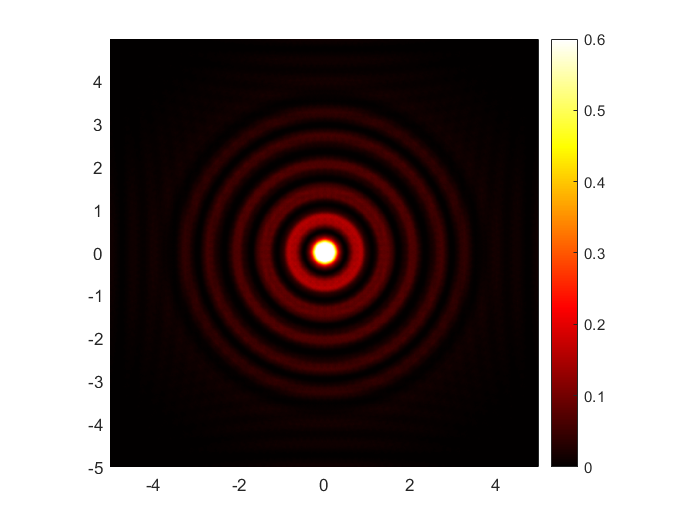

ii = 31

K=31;

%Gss(1)=getframe;
for ii=2:nz+1
    u=ifft2(prp.*fft2(u));
    ux(:,ii)=u(N/2+1,:);
    uy(ii,:)=u(:,N/2+1);
    uz(ii)=u(N/2+1,N/2+1);
    W(:,ii,:)=u;
    pcolor(x,x,abs(u).^2); shading flat; axis square;
    colormap hot
    caxis([0 .6]); colorbar
    Gss(ii)=getframe;
    %pause(0.5)
    ii
end

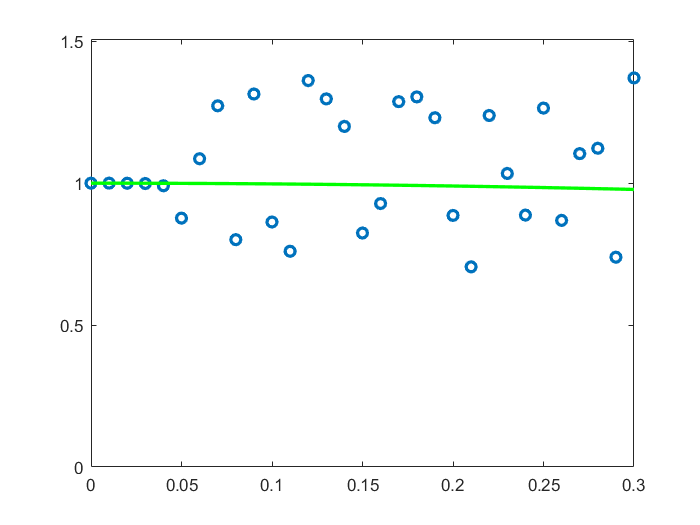


iuza=abs(uz).^2;

figure(1)
plot(z,iuza,'o',z,1./(1+(z.^2)./4),'g','LineWidth',2)
axis([-inf inf 0 1.1*max(iuza)])

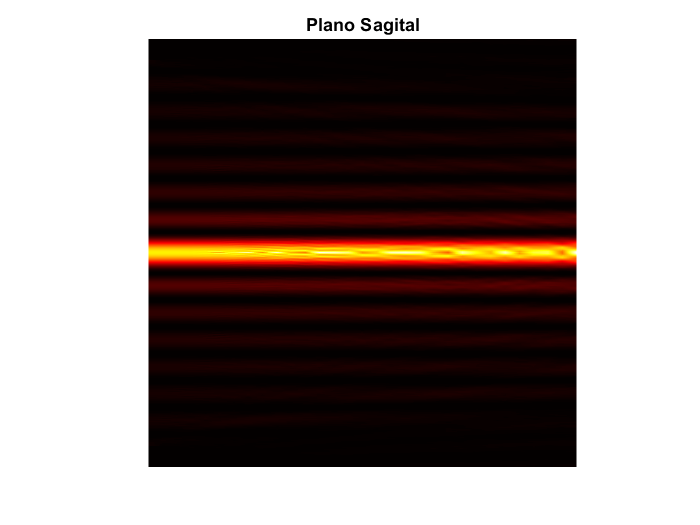




figure(2)
%pcolor(z,x,log(1+ux.*conj(ux))); shading interp; axis square;
pcolor(z,x,abs(ux).^2); shading interp; axis square;
colormap(hot);
title('Plano Sagital')
axis off

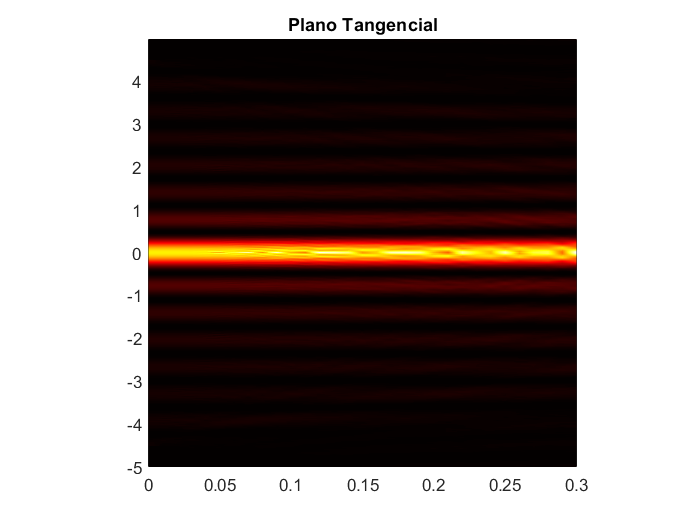

 figure(3)
 %pcolor(z,x,log(1+uy'.*conj(uy'))); shading interp; axis square;
 %pcolor(z,x,log(1+uy'.*conj(uy'))); shading interp; axis square;
 pcolor(z,x,abs(uy').^2); shading interp; axis square;
 colormap(hot);
 title('Plano Tangencial')

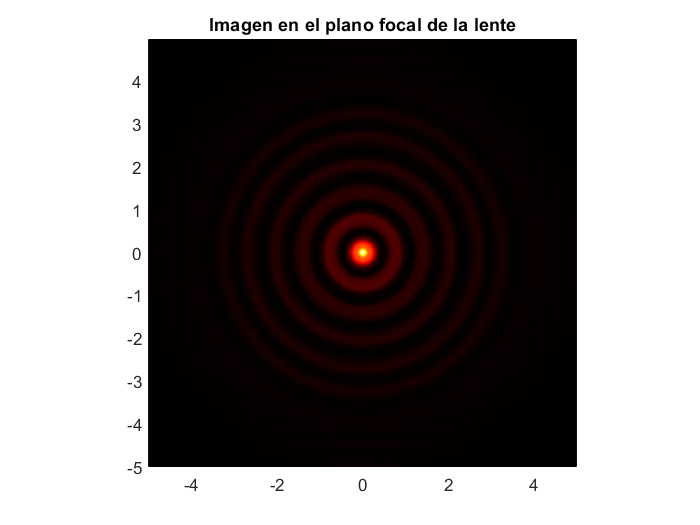

figure(4)
pcolor(x,x,abs(u).^2); shading interp; axis square;
colormap(hot);
title('Imagen en el plano focal de la lente')



figure
[z,x,y]=meshgrid(z,x,x);
xslice = [0,0.05,0.1,0.15,0.20,0.25,0.3]; 
yslice = 0; zslice = 0;
hy=slice(z,x,y,abs(W),xslice,yslice,zslice)

hy =   9×1 Surface array:

  Surface
  Surface
  Surface
  Surface
  Surface
  Surface
  Surface
  Surface
  Surface


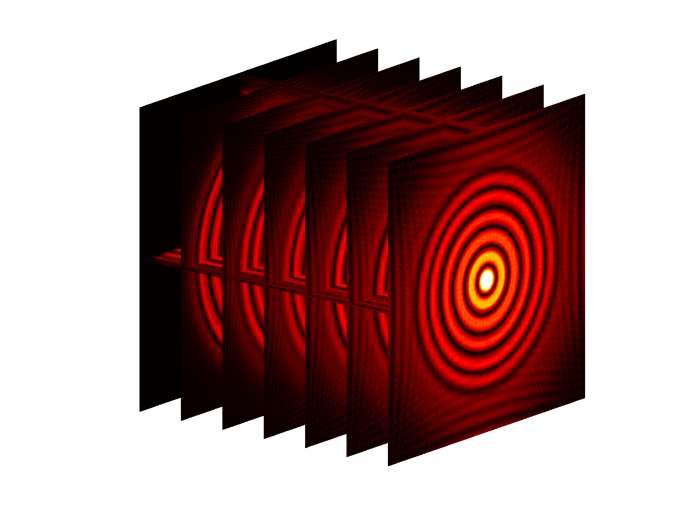

rotate(hy,[-1,0,0],90)
% colormap hsv
shading interp
%camzoom(1.45)
%camproj perspective
alpha(1); %axis off
set(gcf,'Color',[1 1 1])
colormap hot
caxis([0 0.6]);
%caxis([0 1.5]);
view(38.5,16)
%view(145,20);
%camlight; lighting phong
axis off; axis square